syms m [1 7]; %masses of elements
syms I [1 7]; %moments of inertia
syms f1 f2 f3 f4 f5 f6 f7 [3,1]; %forces applied to frame from element
syms s1 s2 s3 s4 s5 s6 s7 [3,1]; %position of each element
syms v1 v2 v3 v4 v5 v6 v7 [3,1]; %position of each element
syms a1 a2 a3 a4 a5 a6 a7 [3,1]; %position of each element
syms t1 t2 t3 t4 t5 t6 t7 [3,1]; %angle of each element
syms tv1 tv2 tv3 tv4 tv5 tv6 tv7 [3,1];
syms ta1 ta2 ta3 ta4 ta5 ta6 ta7 [3,1];
syms w1 w2 w3 w4 w5 w6 w7 [3,1]; %weight of each element
syms gf1 gf2 gf3 gf4 gf5 gf6 gf7 [3,1]; %force on outer gear acting on inner gear
syms l1 l2 l3 l4 l5 l6 l7 [3,1]; %distance from centre to element
syms r [1 7]; %radius of each element
syms gfa [1 7]; %absolute gear force on each eement


syms T_z l3_ab l5_ab Rz Rvector g2 rw l7_ab C_friction7;
syms T [3,1];
syms F_react5 [3,1];
syms M_react5 [3,1];
syms F_react6 [3,1];
syms M_react6 [3,1];
syms F_react7 [3,1];

f=sym([f1, f2, f3, f4, f5, f6, f7]);
gf=sym([gf1, gf2, gf3, gf4, gf5, gf6, gf7]);
s=sym([s1, s2, s3, s4, s5, s6, s7]);
v=sym([v1, v2, v3, v4, v5, v6, v7]);
a=sym([a1, a2, a3, a4, a5, a6, a7]);
t=sym([t1, t2, t3, t4, t5, t6, t7]);
tv=sym([tv1, tv2, tv3, tv4, tv5, tv6, tv7]);
ta=sym([ta1, ta2, ta3, ta4, ta5, ta6, ta7]);
l=sym([l1, l2, l3, l4, l5, l6, l7]);
w=sym([w1, w2, w3, w4, w5, w6, w7]);

g= [0, -g2, 0].';
g=sym(g);

%t = [zeros(1,7); zeros(1,7); t_z]
%tv = [zeros(1,7); zeros(1,7); tv_z]
%ta = [zeros(1,7); zeros(1,7); ta_z]

T = [0; 0; T_z];




w_eqns = w == m.*g;
%w_eqns = reshape(w_eqns1,21,1)

%w_eqns = [w12 == 1; w22 == 2; w32 == 3; w42 == 4; w52 == 5; w62 == 6; w72 == 7;]
%sumeq = [eqtest; w_eqns]
%expr = eliminate(sumeq, w)
%a = solve(sumeq)
%b = solve(sumeq, m1)

%w_eqns = [w1 == m1*g;
%    w2 == m2*g;
%    w3 == m3*g;
%w4 == m4*g;
%    w5 == m5*g;
%   w6 == m6*g;
%  w7 == m7*g;]

%v_eqns = v == diff(s, t)
%a_eqns = a == diff(a, t)
%cond = [s(0) == 0,v(0) == 0,a(0) == 0,]
%k_eqns = [v_eqns, a_eqns, cond]
%k_eqns = reshape(k_eqns,21*5,1)

Rz = [cos(t13), sin(t13), 0;
    -sin(t13), cos(t13), 0;
    0, 0, 1];

Rvector = [cos(t13); -sin(t13); 0];
Rvector2 = [sin(t13); cos(t13); 0];
Rvector7 = [cos(t73); -sin(t73); 0];


%Position setting
l_eqns = [l1==0, l2==0, l3==l3_ab*Rvector,l4==-l3_ab*Rvector,l5==l5_ab*Rvector,l6==-l5_ab*Rvector,l7==l7_ab*Rvector7];

gf_eqns = [gf1==0, gf2==0, gf3==gfa3*Rvector2, gf4==gfa4*Rvector2, gf5==gfa5*Rvector2, gf6==gfa6*Rvector2, gf7 == 0];


gfa_eqns = zeros(3,7);

gfa_eqns= sym(gfa_eqns);

for i=3:6
    for j = 1:2
        gfa_eqns(j,i) = isolate(gf_eqns(j,i),gfa(i));
    end    
end

roll_constraints = [a51 == ta53*rw, a52 == 0, a53 == 0, v51 == tv53*rw, v52 == 0, v53 == 0, ((F_react6==0).'),((M_react6==0).') ];

flip_constraints = [roll_constraints, ta53 == 0, tv53 == 0];
f_constraints = f(3,:) == 0;
%gf_constraints = gf(3,:) == 0
s_constraints = s(3,:) == 0;
v_constraints = v(3,:) == 0;
a_constraints = a(3,:) == 0;
%T_constraint = T == [0, 0, Ta]
t_constraints = t(1:2,:) == 0;
tv_constraints = tv(1:2,:) == 0;
ta_constraints = ta(1:2,:) == 0;

f_constraints = reshape(f_constraints,7,1);
%gf_constraints = reshape(gf_constraints,7,1);
s_constraints = reshape(s_constraints,7,1);
v_constraints = reshape(v_constraints,7,1);
a_constraints = reshape(a_constraints,7,1);
t_constraints = reshape(t_constraints,14,1);
tv_constraints = reshape(tv_constraints,14,1);
ta_constraints = reshape(ta_constraints,14,1);


a_eqns = [a1 == a2,    a2 == a5 + cross(-l5, ta1) + cross(cross(tv1,-l5),tv1),    a3 == a2 + cross(l3, ta1) + cross(cross(tv1,l3),tv1),  a4 == a2 + cross(l4, ta1) + cross(cross(tv1,l4),tv1),    a5 == a2 + cross(l5, ta1) + cross(cross(tv1,l5),tv1),    a6 == a2 + cross(l6, ta1) + cross(cross(tv1,l6),tv1)];
a_eqns2 = a_eqns;
a_eqns2(:,[1, 3:6]) = subs(a_eqns(:,[1, 3:6]), a2, a5 + cross(-l5, ta1) + cross(cross(tv1,-l5),tv1))




v_eqns = [v1 == v2,...
    v2 == v5 + cross(-l5, tv1),...
    v3 == v2 + cross(l3, tv1),...
    v4 == v2 + cross(l4, tv1),...
    v5 == v2 + cross(l5, tv1),...
    v6 == v2 + cross(l6, tv1),...
    ];

s_eqns = [s1 == s2;
    s2 == s5 + -l5;
    s3 == s2 + l3;
    s4 == s2 + l4;
    s5 == s2 + l5;
    s6 == s2 + l6;
    ];
ta_eqns = [ta3-ta1 == -r2/r3*(ta2-ta1);
    ta4-ta1 == -r2/r3*(ta2-ta1);
    ta5-ta1 == -r5/r3*(ta3-ta1);
    ta6-ta1 == -r5/r3*(ta4-ta1);
    ];

tv_eqns = [tv3-tv1 == -r2/r3*(tv2-tv1);
    tv4-tv1 == -r2/r3*(tv2-tv1);
    tv5-tv1 == -r2/r3*(tv3-tv1);
    tv6-tv1 == -r2/r3*(tv4-tv1);
    ];
tv_eqns2 = zeros(12,1);

tv_eqns2= sym(tv_eqns2);
tv_temp=unwrapy(tv(:,3:7));
for i=1:12
        tv_eqns2(i) = isolate(tv_eqns(i),tv_temp(i));
end

ta_eqns2 = zeros(12,1);

ta_eqns2= sym(ta_eqns2);
ta_temp=unwrapy(ta(:,3:7));
for i=1:12
        ta_eqns2(i) = isolate(ta_eqns(i),ta_temp(i));
end

r_eqns = [r4==r3;
    r6==r5;
    l3_ab==r2+r3;
    l5_ab==r2+2*r3+r5];





f_eqns= [m1*a1 == f2+f3+f4+f5+f6+f7+w1, m2*a2 == w2-f2+gf3+gf4, m3*a3 == w3-f3-gf3+gf5,    m4*a4 == w4-f4-gf4+gf6,m5*a5 == w5-f5-gf5+F_react5,    m6*a6 == w6-f6-gf6+F_react6];

M_eqns = [I1*-ta1 == cross(l3,f3) + cross(l4,f4) + cross(l5,f5) + cross(l6,f6);
    I2*ta23 == T_z - r2*gfa3 + r2*gfa4;
    I3*ta33 == -r3 * gfa3 - r3* gfa5;
    I4*ta43 == r4 * gfa4 + r4* gfa6;
    I5*ta53 == -r5 * gfa5 + M_react53;
    I6*ta63 == r6 * gfa6 + M_react63
    ];




f7_eqs = [m7*a7==-f7+F_react7+w7; I7*ta7 == T + cross(-l7/2, w7) + cross(-l7, F_react7)]
f7_eqs = f7_eqs([1:2, 6])

a7_eqs = [a7== a1+ cross(l7/2, ta7)]
s7_eqs = [l72==(rw-l52), l71 == sqrt(l7_ab.^2-l72.^2), ... 
    ta73 == ((l7_ab^2 - l72^2)*a22 + l72*v22^2)/(l7_ab^3 * (1 - l72^2/l7_ab^2)^(3/2))] %From wolfram alpha derivation

f7_eqs = subs(f7_eqs, lhs(a7_eqs), rhs(a7_eqs));
f7_eqs = subs(f7_eqs, lhs(s7_eqs), rhs(s7_eqs));
f7_eqs = subs(f7_eqs, lhs(s7_eqs), rhs(s7_eqs));
f7_eqs = subs(f7_eqs, lhs(w_eqns), rhs(w_eqns));
f7_eqs = subs(f7_eqs, lhs(ta_constraints), rhs(ta_constraints))

Fr_7_eqs = [F_react71 ==  -C_friction7*F_react72];
f7_eqs = subs(f7_eqs, lhs(Fr_7_eqs), rhs(Fr_7_eqs));

Fr_7_eqs = isolate(f7_eqs(3), F_react72);
f7_eqs = f7_eqs([1:2]);
f7_eqs = subs(f7_eqs, lhs(Fr_7_eqs), rhs(Fr_7_eqs));
f7_eqs(1) = isolate(f7_eqs(1), f71);
f7_eqs(2) = isolate(f7_eqs(2), f72)



a7_eqs = subs(a7_eqs(1:2),lhs(a_eqns2), rhs(a_eqns2)) 

%Eliminate 0 variables
M_eqns2 = M_eqns(3:8);
f_eqns2 = f_eqns(1:2,:);
%add f7 equations
f_eqns2(1:2,7)=f7_eqs

%substitute l
M_eqns3 = subs(M_eqns2, l, rhs(l_eqns))



%substitute w
f_eqns3 = subs(f_eqns2, w, rhs(w_eqns));
%substitute gf
f_eqns4 = subs(f_eqns2, gf, rhs(gf_eqns));

syms gfa_eqns [2 7];



%manual calcs

%flip only condition
f_eqns5 = subs(f_eqns4, lhs(flip_constraints), rhs(flip_constraints));
M_eqns5 = subs(M_eqns3, lhs(flip_constraints), rhs(flip_constraints));

%weight
f_eqns6 = subs(f_eqns5, lhs(w_eqns), rhs(w_eqns));



%eliminate gfa5, 6
M_eqns6= M_eqns5(1:4);
gfa_subs=M_eqns5(5:6);
gfa_subs(1)=isolate(gfa_subs(1),gfa5);
gfa_subs(2)=isolate(gfa_subs(2),gfa6);

f_eqn = subs(f_eqns6, lhs(gfa_subs), rhs(gfa_subs));
M_eqn = subs(M_eqns6, lhs(gfa_subs), rhs(gfa_subs));


%eliminate gfa3, 4
gfa_subs=M_eqn(3:4);
M_eqn= M_eqn(1:2);
gfa_subs(1)=isolate(gfa_subs(1),gfa3);
gfa_subs(2)=isolate(gfa_subs(2),gfa4);

f_eqn = subs(f_eqn, lhs(gfa_subs), rhs(gfa_subs))
M_eqn = subs(M_eqn, lhs(gfa_subs), rhs(gfa_subs))


%eliminate forces
f_subs=f_eqn(:,2:7)
for i = 1:6
    f_subs(1,i)=isolate(f_subs(1,i),f(1,i+1));
    f_subs(2,i)=isolate(f_subs(2,i),f(2,i+1));
end
f_subs
f_eqn=f_eqn(:,1)

f_eqn = subs(f_eqn, lhs(f_subs), rhs(f_subs))
M_eqn = subs(M_eqn, lhs(f_subs), rhs(f_subs))


%eliminate reaction forces
f_eqn(1)=isolate(f_eqn(1),F_react51);
f_eqn(2)=isolate(f_eqn(2),F_react52);
M_eqn = subs(M_eqn, lhs(f_eqn), rhs(f_eqn))


%eliminate accelleration
M_eqn = subs(M_eqn, lhs(a_eqns), rhs(a_eqns));
M_eqn = subs(M_eqn, lhs(a_eqns(:,[1:4, 6])), rhs(a_eqns(:,[1:4, 6])));
M_eqn = subs(M_eqn, lhs(flip_constraints), rhs(flip_constraints));


M_eqn = subs(M_eqn, lhs(ta_constraints), rhs(ta_constraints));
M_eqn = subs(M_eqn, lhs(ta_eqns2), rhs(ta_eqns2));
M_eqn = subs(M_eqn, lhs(ta_eqns2), rhs(ta_eqns2));

M_eqn = subs(M_eqn, lhs(tv_constraints), rhs(tv_constraints));
M_eqn = subs(M_eqn, lhs(tv_eqns2), rhs(tv_eqns2));
M_eqn = subs(M_eqn, lhs(tv_eqns2), rhs(tv_eqns2));

M_eqn = subs(M_eqn, lhs(v_eqns), rhs(v_eqns));
M_eqn = subs(M_eqn, lhs(v_eqns(:,[1:4, 6])), rhs(v_eqns(:,[1:4, 6])));

M_eqn(1) = isolate(M_eqn(1), ta13);
M_eqn(2) = isolate(M_eqn(2), ta23);


M_eqn = subs(M_eqn, lhs(l_eqns), rhs(l_eqns));
M_eqn = subs(M_eqn, lhs(r_eqns), rhs(r_eqns))


m_subs = M_eqn(2);
M_eqn = M_eqn(1);
ta_subs=subs(ta_eqns2(9),lhs(ta_eqns2(3)), rhs(ta_eqns2(3)));
ta_subs=isolate(ta_subs,ta23);
m_subs = subs(m_subs, lhs(ta_subs), rhs(ta_subs));
m_subs = subs(m_subs, lhs(flip_constraints), rhs(flip_constraints));
M_eqn = subs(M_eqn, lhs(ta_subs), rhs(ta_subs))
M_eqn = subs(M_eqn, lhs(flip_constraints), rhs(flip_constraints))

m_subs = isolate(m_subs,M_react53);

M_eqn = subs(M_eqn, lhs(m_subs), rhs(m_subs))
M_eqn = isolate(M_eqn,ta13)

M_eqn= combine(M_eqn, 'sincos');
%M_eqn= ta13 == simplify(rhs(M_eqn))


%set design parameters
design_parameters = [rw==0.075;
    r2==0.04;
    r3==0.02;
    r5==0.015;
    l7_ab==0.4;
    I7== 0.1;
    m1==0.1;
    m2==1e-10;
    m3==1e-10;
    m4==1e-10;
    m5==0.05;
    m6==0.05
    m7==0.1;
    I1==0.01;
    I2==1e-10;
    I3==1e-10;
    I4==1e-10;
    I5==0.005;
    I6==0.005;
    g2==9.81;
    C_friction7==0.1];
%apply to eq
Q_eqn=subs(M_eqn, lhs(design_parameters), rhs(design_parameters))
Q_eqn= ta13 == simplify(rhs(Q_eqn))

testeqn= ta13 == simplify(rhs(subs(Q_eqn, [tv13], [0])))
testeqn= ta13 == simplify(rhs(subs(testeqn, [t13], [0])))

%create plot of required torque vs position
P_eqn=subs(Q_eqn, [tv13, ta13], [0, 0])
P_eqn=isolate(P_eqn, T_z)
xvals=linspace(0, pi/2, 100)
yvals = linspace(0, 0, 100)
syms Tf(t13)
Tf(t13) = rhs(P_eqn)
fplot(Tf(t13), [0, pi/2])

%for i = 1:100
%    yvals=rhs(subs(P_eqn, t13, xvals(i)))
%end
%plot(xvals, yvals)

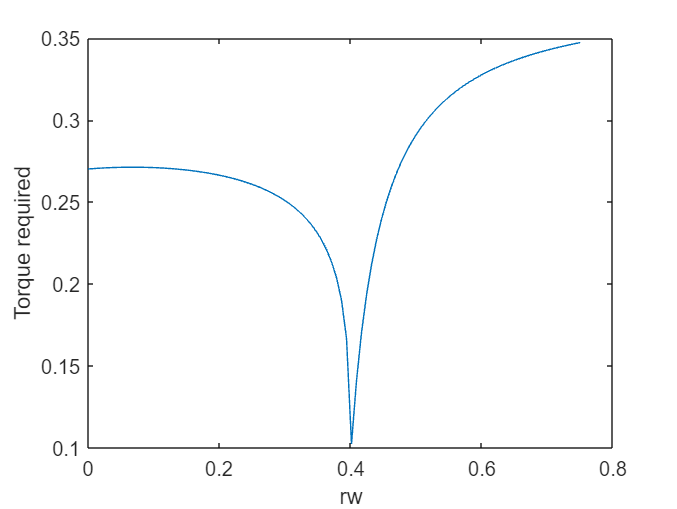

syms Tf
hold off

for i=1:length(design_parameters)
    P_eqn=subs(M_eqn, lhs(design_parameters(1:end ~=i)), rhs(design_parameters(1:end ~=i)));
    P_eqn=subs(P_eqn, [tv13, ta13, t13], [0, 0, 0]);
    P_eqn=isolate(P_eqn, T_z);
    Tf(lhs(design_parameters(i))) = rhs(P_eqn);
    xvals=linspace(1e-10, 10*rhs(design_parameters(i)), 100)
    yvals = linspace(0, 0, 100);
    for k = 1:100
        yvals(k)=real(simplify(rhs(subs(P_eqn, lhs(design_parameters(i)), xvals(k)))));
    end
    yvals
    plot(xvals, yvals)
    %fplot(Tf(lhs(design_parameters(i))), [0, 10*rhs(design_parameters(i))]);
    ylabel("Torque required")
    xlabel(string(lhs(design_parameters(i))))
end    

yvals =     0.2701    0.2704    0.2706    0.2707    0.2709    0.2710    0.2711    0.2712    0.2712    0.2712    0.2712    0.2712    0.2711    0.2710    0.2709    0.2707    0.2705    0.2703    0.2701    0.2698    0.2694    0.2691    0.2687    0.2682    0.2677    0.2672    0.2666    0.2660    0.2653    0.2645    0.2637    0.2628    0.2618    0.2608    0.2596    0.2584    0.2570    0.2555    0.2539    0.2521    0.2501    0.2479    0.2454    0.2426    0.2395    0.2359    0.2317    0.2268    0.2208    0.2134


yvals =    -0.0000   -0.0567   -0.2222   -2.3649    0.7018    0.4157    0.3368    0.3025    0.2851    0.2757    0.2709    0.2688    0.2684    0.2693    0.2710    0.2733    0.2761    0.2792    0.2826    0.2861    0.2898    0.2936    0.2975    0.3014    0.3054    0.3094    0.3135    0.3175    0.3215    0.3255    0.3295    0.3335    0.3375    0.3414    0.3454    0.3492    0.3531    0.3569    0.3607    0.3645    0.3682    0.3719    0.3756    0.3792    0.3828    0.3863    0.3899    0.3934    0.3968    0.4002


yvals =     0.1776    0.1882    0.1984    0.2085    0.2182    0.2278    0.2371    0.2461    0.2550    0.2636    0.2721    0.2803    0.2884    0.2962    0.3039    0.3115    0.3188    0.3260    0.3331    0.3400    0.3467    0.3534    0.3598    0.3662    0.3724    0.3785    0.3845    0.3904    0.3961    0.4017    0.4073    0.4127    0.4180    0.4233    0.4284    0.4334    0.4384    0.4432    0.4480    0.4527    0.4573    0.4619    0.4663    0.4707    0.4750    0.4792    0.4834    0.4875    0.4915    0.4955


yvals =     0.1641    0.1721    0.1806    0.1896    0.1992    0.2094    0.2204    0.2321    0.2446    0.2581    0.2727    0.2885    0.3057    0.3244    0.3449    0.3674    0.3922    0.4198    0.4506    0.4852    0.5243    0.5689    0.6204    0.6802    0.7508    0.8352    0.9380    1.0659    1.2294    1.4456    1.7452    2.1879    2.9080    4.2857    7.9789   50.5284  -11.9944   -5.4278   -3.5350   -2.6359   -2.1106   -1.7662   -1.5229   -1.3419   -1.2020   -1.0906   -0.9999   -0.9245   -0.8608   -0.8064


yvals =     0.0847    0.0687    0.0768    0.1525    0.1874    0.2111    0.2289    0.2430    0.2544    0.2639    0.2720    0.2789    0.2849    0.2902    0.2949    0.2990    0.3028    0.3062    0.3092    0.3120    0.3146    0.3169    0.3191    0.3211    0.3230    0.3247    0.3263    0.3278    0.3292    0.3306    0.3318    0.3330    0.3341    0.3351    0.3361    0.3371    0.3380    0.3388    0.3396    0.3404    0.3412    0.3419    0.3425    0.3432    0.3438    0.3444    0.3450    0.3455    0.3460    0.3465


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


yvals =     0.1631    0.1741    0.1850    0.1959    0.2068    0.2177    0.2286    0.2396    0.2505    0.2614    0.2723    0.2832    0.2941    0.3051    0.3160    0.3269    0.3378    0.3487    0.3596    0.3706    0.3815    0.3924    0.4033    0.4142    0.4252    0.4361    0.4470    0.4579    0.4688    0.4797    0.4907    0.5016    0.5125    0.5234    0.5343    0.5452    0.5562    0.5671    0.5780    0.5889    0.5998    0.6107    0.6217    0.6326    0.6435    0.6544    0.6653    0.6763    0.6872    0.6981


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


yvals =     0.1631    0.1741    0.1850    0.1959    0.2068    0.2177    0.2286    0.2396    0.2505    0.2614    0.2723    0.2832    0.2941    0.3051    0.3160    0.3269    0.3378    0.3487    0.3596    0.3706    0.3815    0.3924    0.4033    0.4142    0.4252    0.4361    0.4470    0.4579    0.4688    0.4797    0.4907    0.5016    0.5125    0.5234    0.5343    0.5452    0.5562    0.5671    0.5780    0.5889    0.5998    0.6107    0.6217    0.6326    0.6435    0.6544    0.6653    0.6763    0.6872    0.6981


yvals =     0.2162    0.2217    0.2273    0.2328    0.2384    0.2440    0.2495    0.2551    0.2607    0.2662    0.2718    0.2773    0.2829    0.2885    0.2940    0.2996    0.3051    0.3107    0.3163    0.3218    0.3274    0.3329    0.3385    0.3441    0.3496    0.3552    0.3607    0.3663    0.3719    0.3774    0.3830    0.3886    0.3941    0.3997    0.4052    0.4108    0.4164    0.4219    0.4275    0.4330    0.4386    0.4442    0.4497    0.4553    0.4608    0.4664    0.4720    0.4775    0.4831    0.4887


yvals =     0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712    0.2712


function unwrapped = unwrapy(x)
    bigness=size(x);
    L_x=bigness(1)*bigness(2);
    unwrapped = sym(zeros(L_x,1));
    for i=1:bigness(1)
        for j=1:bigness(2)
            unwrapped(i+bigness(1)*(j-1)) = x(i,j);
        end
    end
end

function unwrapped = unwrapx(x)
    bigness=size(x);
    L_x=bigness(1)*bigness(2);
    unwrapped = sym(zeros(1,L_x));
    for i=1:bigness(1)
        for j=1:bigness(2)
            unwrapped(1,i+bigness(1)*(j-1)) = x(i,j);
        end
    end
end